# (2) 混合分布モデルによる異常検知

## はじめに

ホテリングの$T^2$法は、多次元データに対して、比較的少ない計算量で異常度を計算できるという利点があります。しかし一方で、データの分布が単峰性の場合しかうまく適合しないという欠点があります。このためデータの分布が多峰性 (多次元空間内でクラスタが複数存在) の場合は、別の手法が必要となります。

混合分布モデルは、そのようなケースに適用可能な手法の1つです。このモデルでは、データ点は、多次元空間内で複数の点を中心とする複数のクラスタとして存在すると仮定します。そのうえで、各クラスタのデータ分布をガウス分布で近似します。このため、発生頻度 X% の異常を検出するには、これらガウス分布の和を確率密度関数として考えて、X%に対応する閾値を決めれば良いことになります。

ガウス分布の和による近似をおこなうためには、EM (Expectation-Maximization) アルゴリズムを用いて個々のガウス分布を特徴づけるパラメータの最尤推定 (maximum likelihood estimation) をおこないます。

## 前処理済みのデータの読み込み

あらかじめ作成した前処理済みのデータを読み込みます。

load('Preprocessed_FD001.mat');

## 混合分布モデルの構築

簡単のため、以下では第1主成分-第2主成分平面上でのデータ分布に対して、混合分布モデルを構築します。

まず、'long' とラベル付けされたデータを「正常データ」と想定して、EMアルゴリズムにより混合分布モデルを構築します。

次に、異常を判別するための閾値として、発生頻度が 5%, 1% および 0.1% を想定し、上記で構築した混合分布モデルからそれぞれに対応する閾値を求めます。

最後に、主成分平面上でのデータ点の分布と、発生頻度 5%, 1% および 0.1% の異常を判別するための境界線を図示します。

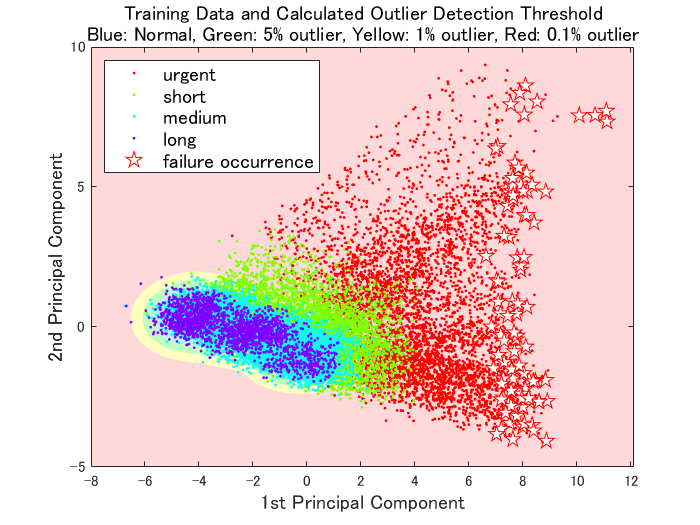

% 最適なクラスタ数を、赤池情報量基準 (AIC: Akaike's Information Criterion) で算出するための準備
idx = (dataTrainZ.Label == 'long');
mdlGM = cell(1,4);
AIC = zeros(1,4);

% クラスタ数 1～4 それぞれに対して混合分布モデルを構築し、それぞれのAICを算出 
rng('default');
options = statset('MaxIter',500);
for kk = 1:4
    mdlGM{kk} = fitgmdist(score(idx,:), kk, 'Options', options);
    AIC(kk) = mdlGM{kk}.AIC;
end

% AICに基づき最適なクラスタ数を決定
[minAIC, numCluster] = min(AIC);

% 最適なクラスタ数で混合分布モデルを構築
rng('default');
options = statset('MaxIter',500);
bestMdlGM = fitgmdist(score(idx,1:2), numCluster, 'Options', options);
d = 0.1;
[x1Grid, x2Grid] = meshgrid(-8:d:8, -8:d:8);
aGrid = pdf(bestMdlGM, [x1Grid(:) x2Grid(:)]);
aGrid = reshape(aGrid, size(x1Grid,1), size(x2Grid,2));

sorted = sort(aGrid(:),'descend');
accum = cumsum(sorted*d*d);

% 発生頻度が 5%, 1% および 0.1% の異常を検出するための閾値を求める
th = [0.001, 0.01, 0.05];
C = cell(3,1);

for kk = 1:3
    idx = find(accum > (1-th(kk)), 1);
    C{kk} = contourc((-8:d:8), (-8:d:8), aGrid, [sorted(idx) sorted(idx)]);
end

% 発生頻度 5%, 1% および 0.1% に対応する色を設定
col5per = [0.75 0.95 1];
col1per = [0.75 1 0.75];
col01per = [1 1 0.75];
colAnomaly = [1 0.85 0.85];

% 結果を可視化
figure
plotContourmatrix(C{1}, col01per);
plotContourmatrix(C{2}, col1per);
plotContourmatrix(C{3}, col5per);
hold on;
s1 = gscatter(score(:,1),...
    score(:,2),...
    dataTrainZ.Label(:));
idx = dataTrainZ.Time == 0;
s2 = plot(score(idx,1),...
    score(idx,2),'rp','MarkerSize',10,'MarkerFaceColor','w');
legend([s1; s2],{'urgent','short','medium','long','failure occurrence'},...
    'Color',    [1 1 1],...
    'Location', 'northwest',...
    'FontSize', 12);
ax = gca;
ax.Color = colAnomaly;
ax.Box = 'on';
xlabel('1st Principal Component','FontSize',12);
ylabel('2nd Principal Component','FontSize',12);
title({'Training Data and Calculated Outlier Detection Threshold';...
    'Blue: Normal, Green: 5% outlier, Yellow: 1% outlier, Red: 0.1% outlier'},'FontSize',12)

## 検証用データによる確認

次に、ホテリングの$T^2$法のデモと同様に、学習用データをもとに算出した閾値を、検証用データに対して適用してみます。その結果、検証用データで 'urgent' とラベル付けされたデータを検出するには、1% 用の閾値を用いると良いということが確認できました。

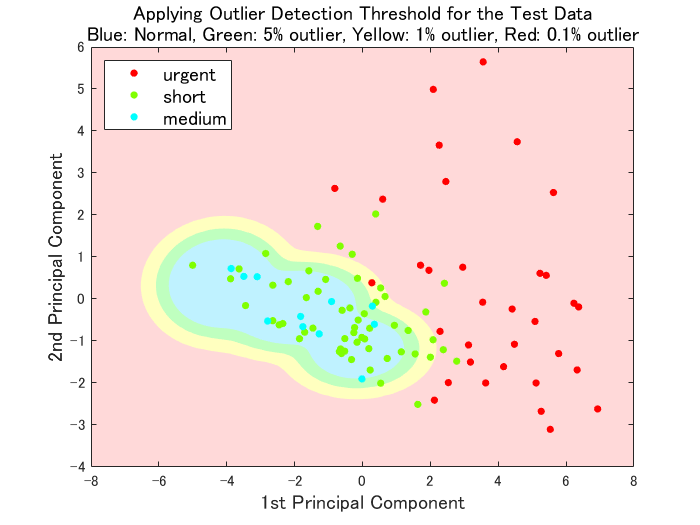

% 検証用データの標準化
dataTestZ = dataTest;
dataTestZ{:,3:end-1} = (dataTest{:,3:end-1} - mu)./sigma;

score = dataTestZ{:,3:end-1}*wcoeff;

% 結果の可視化
figure
plotContourmatrix(C{1}, col01per);
plotContourmatrix(C{2}, col1per);
plotContourmatrix(C{3}, col5per);
hold on;
s1 = gscatter(score(:,1),...
    score(:,2),...
    dataTestZ.Label);
legend(s1,{s1.DisplayName},...
    'Color',    [1 1 1],...
    'Location', 'northwest',...
    'FontSize', 12);
ax = gca;
ax.Color = colAnomaly;
ax.Box = 'on';
xlabel('1st Principal Component','FontSize',12);
ylabel('2nd Principal Component','FontSize',12);
title({'Applying Outlier Detection Threshold for the Test Data';...
    'Blue: Normal, Green: 5% outlier, Yellow: 1% outlier, Red: 0.1% outlier'},'FontSize',12)

*Copyright 2020 The MathWorks, Inc.*